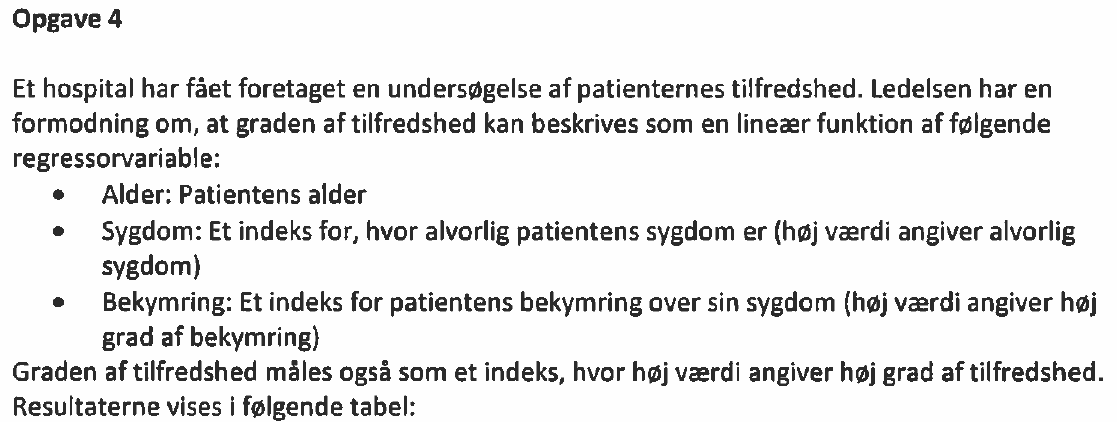

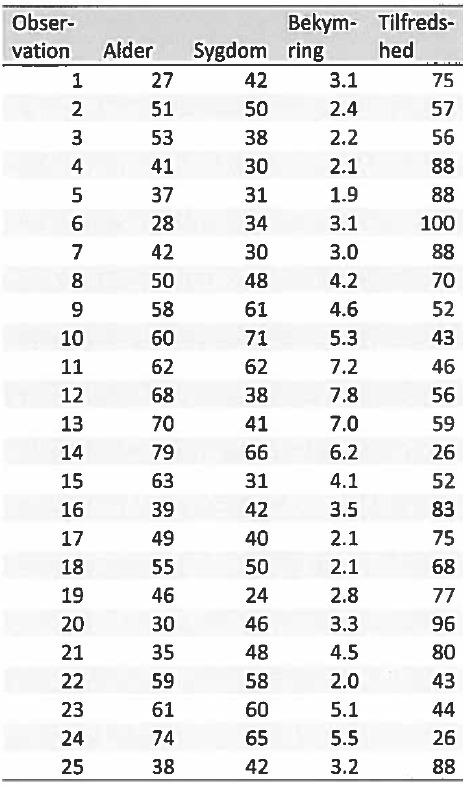

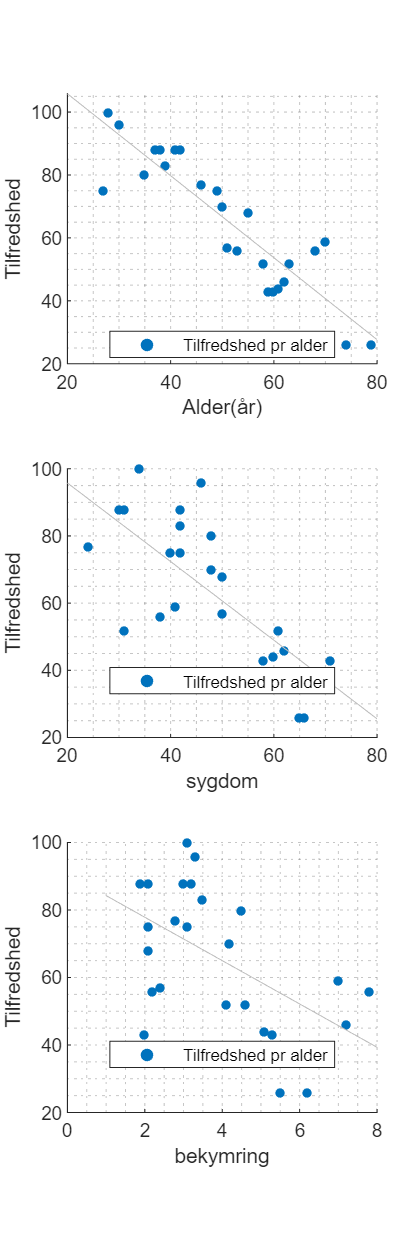

data = xlsread('M4STI_2015_data.xlsx');
alder = data(:, 6);
sygdom = data(:, 7);
bekym = data(:, 8);
Tilfreds = data(:,9);

figure('Position', [10 10 900 2700])

subplot(3,1,1)
subtitle('Tilfredshed ift alder');
a = scatter(alder, Tilfreds, 20, 'filled', DisplayName='Tilfredshed pr alder');
lsline%(a, DisplayName='Forsommer')%(DisplayName='lsline forsommer');
% lsline;
xlabel('Alder(år)');
ylabel('Tilfredshed');
legend([a],Location="best")
grid('minor')

subplot(3,1,2)
subtitle('Tilfredshed ift alder');
a = scatter(sygdom, Tilfreds, 20, 'filled', DisplayName='Tilfredshed pr alder');
lsline%(a, DisplayName='Forsommer')%(DisplayName='lsline forsommer');
% lsline;
xlabel('sygdom');
ylabel('Tilfredshed');
legend([a],Location="best")
grid('minor')

subplot(3,1,3)
subtitle('Tilfredshed ift alder');
a = scatter(bekym, Tilfreds, 20, 'filled', DisplayName='Tilfredshed pr alder');
lsline%(a, DisplayName='Forsommer')%(DisplayName='lsline forsommer');
% lsline;
xlabel('bekymring');
ylabel('Tilfredshed');
legend([a],Location="best")
grid('minor')

mdl = fitlm([alder, sygdom, bekym], Tilfreds)

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)      144.58     5.9902     24.137    8.4778e-17
    x1              -1.1267    0.13655    -8.2515    4.9959e-08
    x2             -0.58727    0.13246    -4.4335    0.00023049
    x3               1.3448     1.0668     1.2605        0.2213


Number of observations: 25, Error degrees of freedom: 21
Root Mean Squared Error: 7.07
R-squared: 0.901,  Adjusted R-Squared: 0.887
F-statistic vs. constant model: 64, p-value = 9.82e-11

Vi får således

Tilfredshed = 144.58 - 1.1267*Alder - 0.58727*Sygdom + 1.3448*Bekymring

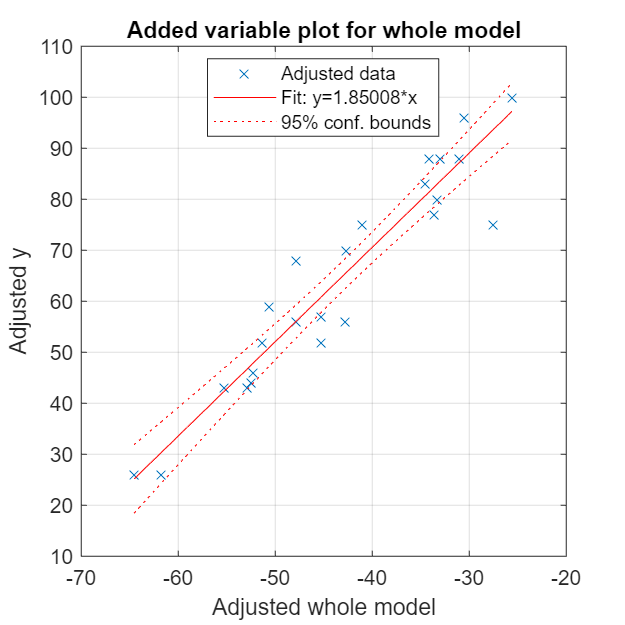

clf
figure('Position', [5 5 400 400])
plot(mdl)
grid

Tilfredshed = 144.58 - 1.1267*60 - 0.58727*45 + 1.3448*3.0

Tilfredshed = 54.5853

Tilfredsheden er således 55

Da vores 

R-adj værdi bliver 0,887 derfor virker dette til at være et nogenlunde fit.

p-værdieren er tæt på 0 for intercept og stiger imod x3 hvilket tilføje til at et godt fit med et stører bidrag fra x1 og x2

F-viser at mindst en variable har indflydelse på modellen hvis dette tal er under significat nivuet

genrelt passer moddel godt bortset fra for x3 (Bekymring). Her er p-værdien 0.2213, så denne koefficient er ikke signifikant forskellig fra 0.

Man kunne fjerne x3 (Bekymring) da den ser ud til at have meget lille indvirkning.